### Почувствовав прилив творческих сил, создал куб

Использовал листинг 1, код комментировал, чтобы ближе к строкам быть

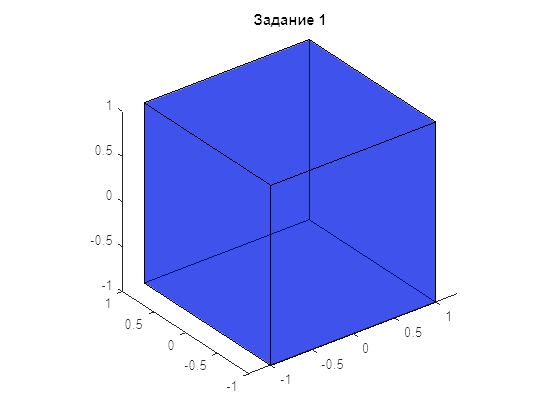

Cube = [
-1, 1, 1,-1,-1, 1, 1 ,-1;
-1,-1, 1, 1,-1,-1, 1, 1;
-1,-1,-1,-1, 1, 1, 1, 1;
1, 1, 1, 1, 1, 1, 1, 1];
% если что, выше задаются вершины

facesCube = [
1, 2, 6, 5;
2, 3, 7, 6;
3, 4, 8, 7;
4, 1, 5, 8;
1, 2, 3, 4;
5, 6, 7, 8];
% тут грани в виде 4 вершин на краях

blue = [0,0.1,0.9,0.5]; % цвет куба ДО преобразований
rgba = [1,0.5,0, 0.5]; % хочу мой фирменный оранжевый для стиля ПОСЛЕ преобразования
title('Задание 1');
Dshow ( Cube , facesCube , blue ) % вызвали отрисовку

### Куб - это хорошо, но мало

Теперь мне предстояло расшириться, ведь куб - это лишь куб, но больший куб даст большие возможности, например, если увеличисть куб в pi раз, мы почувствуем, что это совсем нетривиально, а значит мы смелы и сильны.

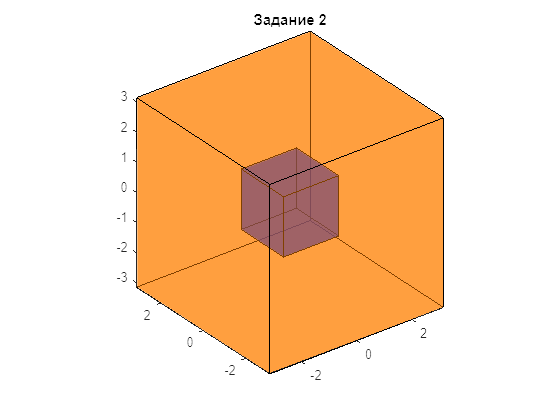

A2=[
    pi,0,0,0;
    0,pi,0,0;
    0,0,pi,0;
    0,0,0,1];
Cube2 = A2 * Cube; % матрицу перехода на каждую строку
title('Задание 2');
Dshow ( Cube2 , facesCube , rgba)

Это, конечно, круто, но до жути банально. Поступим ка кнастоящие панки, и изменим масштаб другой матрицей, а то из куба получать куб...

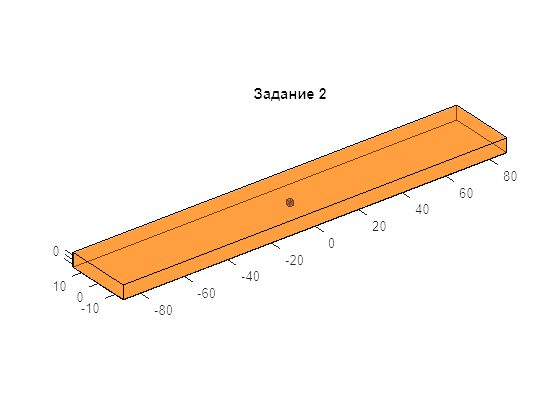

A21=[
    88,0,0,0;
    0,15,0,0;
    0,0,pi,0;
    0,0,0,1];
Cube21 = A21 * Cube;clf;
title('Задание 2');
Dshow ( Cube , facesCube , blue ) % вызвали отрисовку
Dshow ( Cube21 , facesCube , rgba)

## Куб стал таким большим, что загораживает проход, его нужно сместить

Для этих целей решение крайне простое: взять и сдвинуть. Сдвигать буду большой куб из второго задания, и на пи. Куб до преобразований всегда синий, после - оранжевый. 

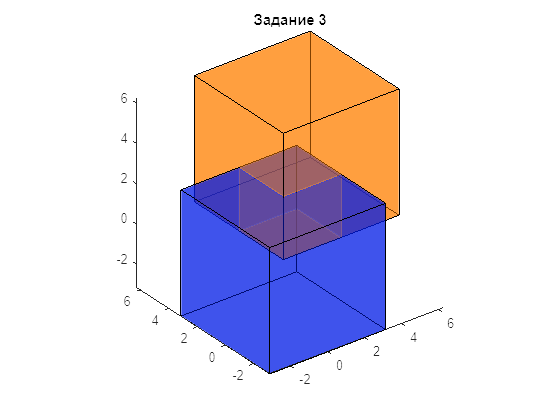

A3=[
    pi;
    pi;
    pi;
    0];
Cube3 = Cube2 + A3; clf;
title('Задание 3');
Dshow ( Cube2 , facesCube , blue);
Dshow ( Cube3 , facesCube , rgba);

При этом дальняя вершина куба, которая после второго задания оказалась в -pi по всем координатам, переместится в начало координат, то есть у куба все координаты станут неотрицательными.

Но это снова не так интересно, ведь так мы долго будем лететь до Марса. Чтобы приземлиться прямёхонько туда, возьмем новую мтарицу. 

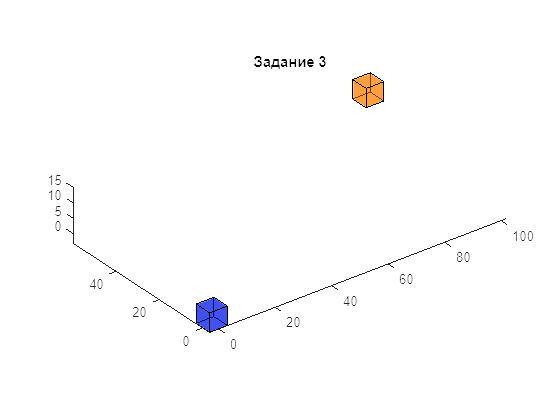

A31=[
    99;
    56.8;
    12;
    0];
Cube31 = Cube2 + A31;clf;
title('Задание 3');
Dshow ( Cube2 , facesCube , blue);
Dshow ( Cube31 , facesCube , rgba);

Совсем другое дело! Более того, из-за такого расстояния размерами теперь можно пренебречь, и вот она, задачка про материальные точки из курса школьной физики. Хотя я потом посмотрел на результат и для наглядности 9999 и 568 заменил на 99 и 56,8.

### Подул ветер, и куб завертелся

Использую матрицу преобразования для поворота кубика. Три. Именно столько видов независимых возможных вращений может существовать в 3D пространстве. Вокург Ох, Оу, Оz. Если добавить к ним смещение по этим же осям, мы получим 6. Это число так и называют: 6 степеней свободы. Поворотам соответствуют матрицы, состоящие из блока обычной матрицы поворота 2х2, значения cos в которой расположены на главной диагонали матрицы поворота 3х3, также на этой диагонали находится 1, ярко выражающая отстутствие преобразований по той оси, координаты по которой не меняются.

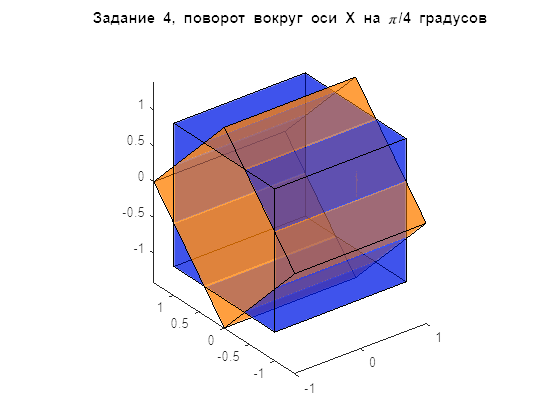

A4X=[
    1,0,0,0;
    0,0.7,-0.7,0;
    0,0.7,0.7,0;
    0,0,0,1];
A4Y=[
    0.7 0,-0.7,0;
    0,1,0,0;
    0.7,0,0.7,0;
    0,0,0,1];
A4Z=[
    0.7,-0.7,0,0;
    0.7,0.7,0,0;
    0,0,1,0;
    0,0,0,1];
Cube4 = A4X * Cube;clf;
title('Задание 4, поворот вокруг оси Х на \pi/4 градусов');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

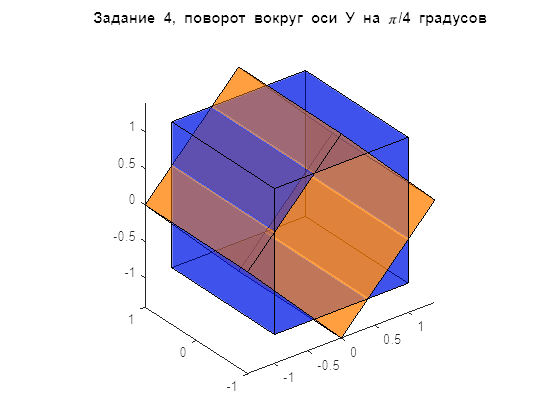

Cube4 = A4Y * Cube;clf;
title('Задание 4, поворот вокруг оси У на \pi/4 градусов');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

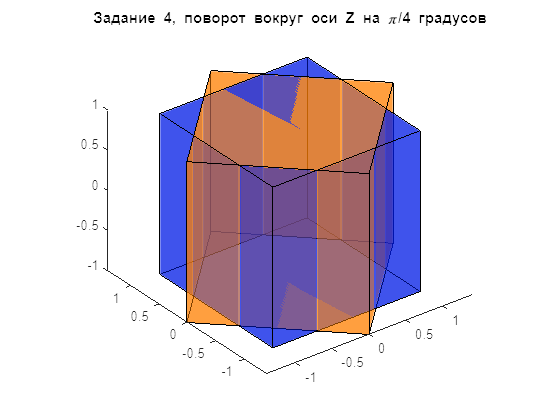

Cube4 = A4Z * Cube; clf;
title('Задание 4, поворот вокруг оси Z на \pi/4 градусов');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

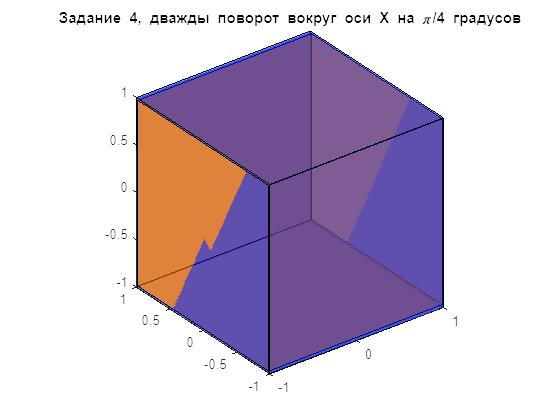

Cube4 = A4X *A4X * Cube;clf;
title('Задание 4, дважды поворот вокруг оси Х на \pi/4 градусов');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

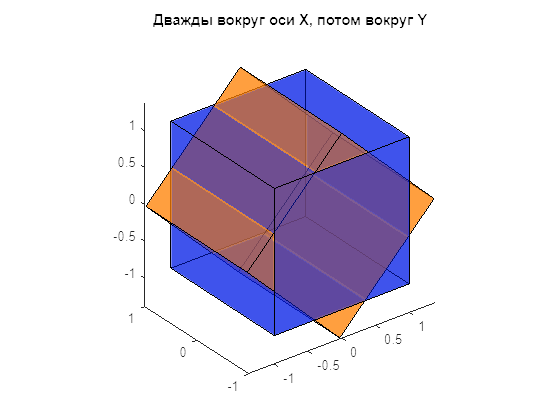

Cube4 = A4Y * A4X * A4X * Cube;clf;
title('Дважды вокруг оси X, потом вокруг Y');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

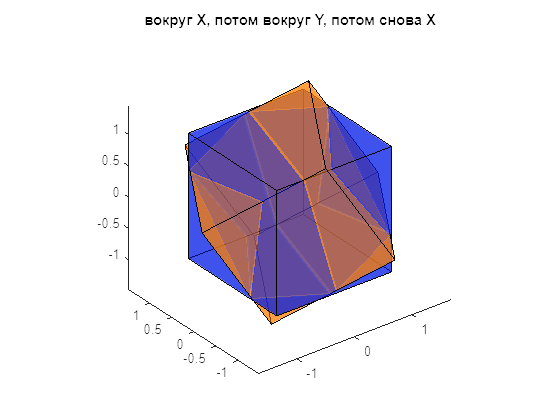

Cube4 = A4X * A4Y * A4X * Cube;clf;
title('вокруг X, потом вокруг Y, потом снова Х');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

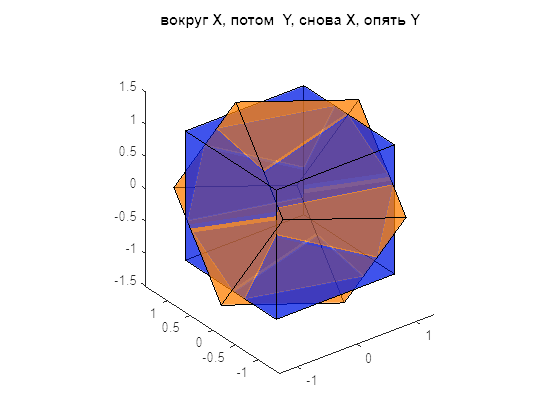

Cube4 = A4Y * A4X * A4Y * A4X * Cube;clf;
title('вокруг X, потом  Y, снова Х, опять Y');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

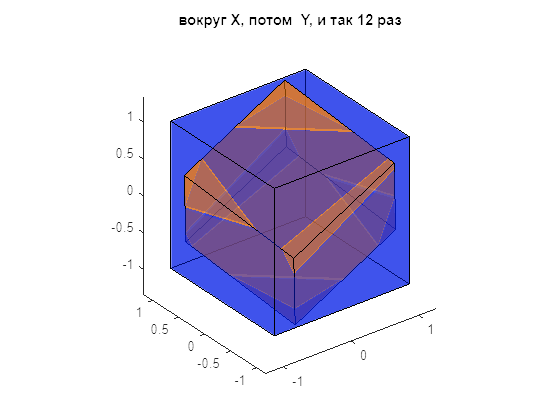

Cube4 = A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * Cube;clf;
title('вокруг X, потом  Y, и так 12 раз');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

Заметно, что мы так и не пришли в исходное состояние. Это легко представить, разложив поворот по действиям:

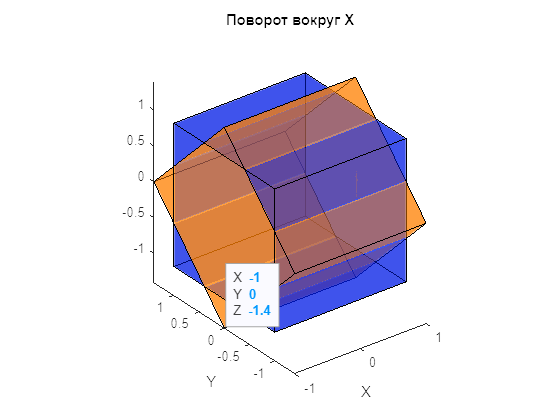

Cube4 = A4X * Cube;clf;
title('Поворот вокруг Х');
xlabel('X');ylabel('Y');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);
ax5 = gca;
chart5 = ax5.Children(1);
datatip(chart5,-1,0,-1.4);
chart5 = ax5.Children(2);
datatip(chart5,-1,1,-1);

Cube4

Cube4 =    -1.0000    1.0000    1.0000   -1.0000   -1.0000    1.0000    1.0000   -1.0000
         0         0    1.4000    1.4000   -1.4000   -1.4000         0         0
   -1.4000   -1.4000         0         0         0         0    1.4000    1.4000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


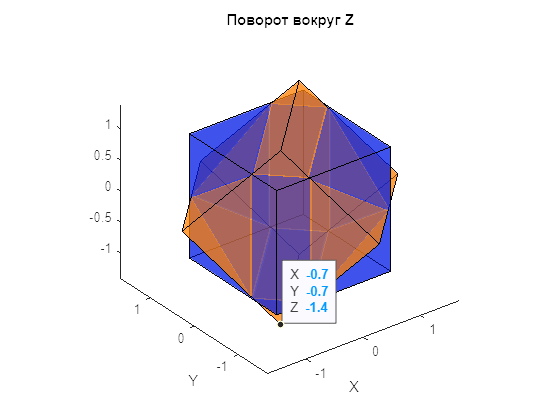

Cube4 = A4Z * Cube4;clf;
title('Поворот вокруг Z');
xlabel('X');ylabel('Y');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);
ax5 = gca;
chart5 = ax5.Children(1);
datatip(chart5,-0.7,-0.7,-1.4);

Cube4

Cube4 =    -0.7000    0.7000   -0.2800   -1.6800    0.2800    1.6800    0.7000   -0.7000
   -0.7000    0.7000    1.6800    0.2800   -1.6800   -0.2800    0.7000   -0.7000
   -1.4000   -1.4000         0         0         0         0    1.4000    1.4000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Cube4 = A4X * Cube4

Cube4 =    -0.7000    0.7000   -0.2800   -1.6800    0.2800    1.6800    0.7000   -0.7000
    0.4900    1.4700    1.1760    0.1960   -1.1760   -0.1960   -0.4900   -1.4700
   -1.4700   -0.4900    1.1760    0.1960   -1.1760   -0.1960    1.4700    0.4900
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


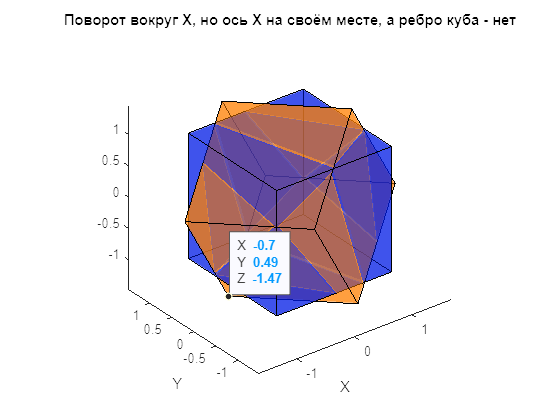

clf;
title('Поворот вокруг Х, но ось Х на своём месте, а ребро куба - нет');
xlabel('X');ylabel('Y');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

ax6 = gca;
chart6 = ax6.Children(1);
datatip(chart6,-0.7,0.49,-1.47);

Из этого можео сделать вывод, что повороты - отнюдь не самая простая штука, не обладающая 3D пространстве свойством коммутативности.

### Чтобы куб не крутился, я пригвоздил одну вершину

Вокруг неё он всё ещё может вращаться. Дабы не заниматься всякой слишком сложной математикой, вспомним, что мы уже умеем вращать кубы вокруг осей, умеем двигать кубы. Возьмем и сдвинем его так, чтобы спокойно вращать вокруг Ох, Оу, Оz, а потом поставим на место.

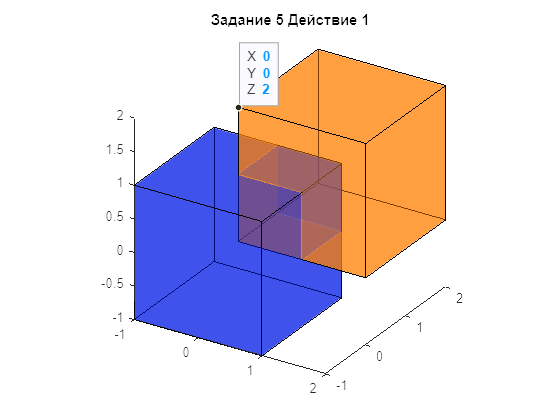

smesheie = [1;1;1;0];
Cube5 = Cube + smesheie;clf;
title('Задание 5 Действие 1');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube5 , facesCube , rgba);
view([32.03 27.00])
ax = gca;
chart = ax.Children(1);
datatip(chart,-2.274,-1.686,1.38);
ax4 = gca;
chart4 = ax4.Children(2);
datatip(chart4,-1,-1,1);

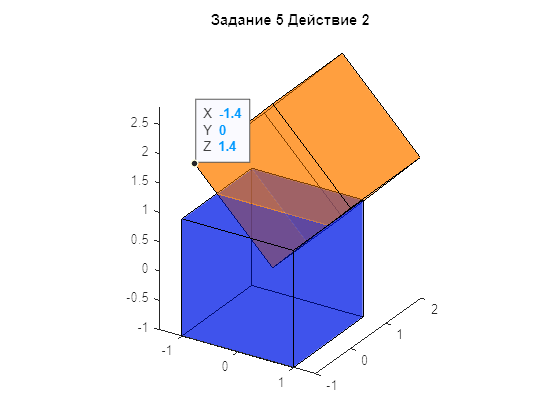

Cube5 = A4Y * Cube5;clf;
title('Задание 5 Действие 2');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube5 , facesCube , rgba);
view([32.03 27.00])
ax = gca;
chart = ax.Children(1);
datatip(chart,-2.274,-1.686,1.38);

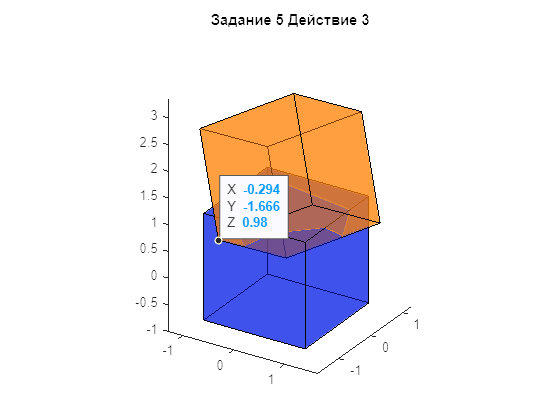


Cube5 = A4Z * A4X * Cube5;clf;
title('Задание 5 Действие 3');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube5 , facesCube , rgba);
view([32.03 27.00])
ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,-0.294,-1.666,0.98);

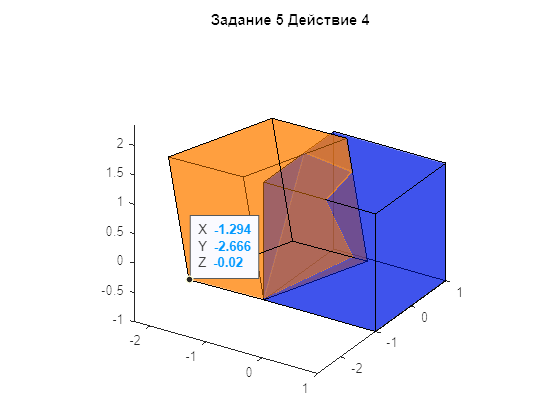


Cube5 = Cube5 - smesheie;clf;
title('Задание 5 Действие 4');
Dshow ( Cube , facesCube , blue);
Dshow ( Cube5 , facesCube , rgba);
view([32.03 27.00])
ax3 = gca;
chart3 = ax3.Children(1);
datatip(chart3,-1.294,-2.666,-0.02);

function DrawShape ( vertices , faces , color ) % принял набор координат вершин, 
% комбинации крайних точек граней, цвет
patch ("Vertices", ( vertices (1:3 ,:) ./ vertices (4 ,:))', "Faces", faces , ...
    "FaceAlpha", color(4), "FaceColor", color(1:3));
% разделили первые три координаты вершины на 4-ю за счёт ./ поэлементно
% это было на тот случай, если мы захотим рисовать под углом
% patch создало поверхность на этих вершинах,
% используя то описание граней и цвет
end

function Dshow ( verticesCube , facesCube , rgba )
DrawShape ( verticesCube , facesCube , rgba ) % вызвали отрисовку
axis equal; % чтобы была ДПСК
view (3); % смотрим в 3D
end